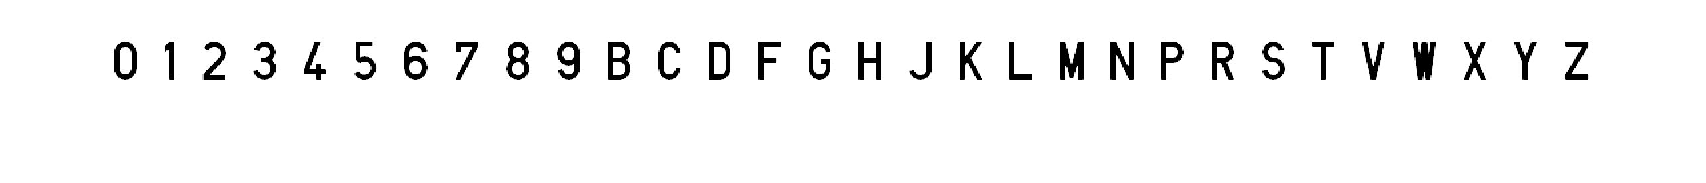

%provem de fer HOG amb una imatge
h = [-1 0 1];
h2 = [-1;0;1];

I = imread('Joc_de_caracters.jpg');

ndg = rgb2gray(I);
imshow(ndg);

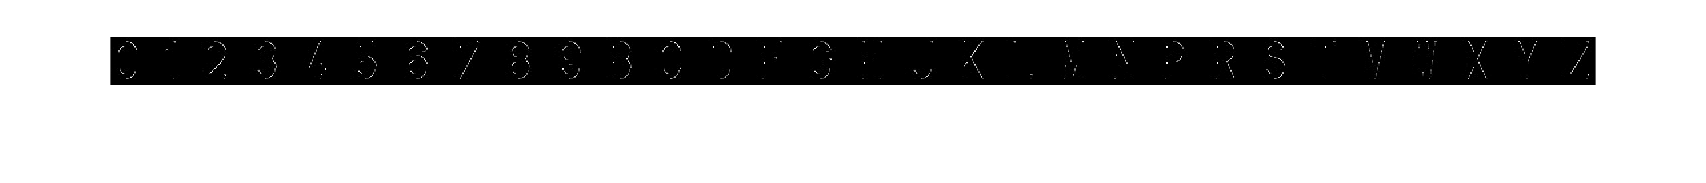

H = imfilter(ndg,h); %contorns horitzontals
VH = imfilter(H,h2); %contorns verticals
imshow(VH,[]);

[F, C] = size(VH);
cellH = floor(F/9);cellW = floor(C/9);
HOGs = cell(9,9); % matrix of histos of bins of pixels
for i = 1:9
    for j = 1:9
        HOGs{i,j} = zeros(1,255);
    end
end
%calculate vale of each cell: histogram of gradients of pixels
for i = 1:9
    for j = 1:9
        s = 0;
        for k = 1:cellH
            for m = 1:cellW
                %count value of gradient into histogram of cell
                grad = VH(k+(i-1)*cellH,m+(j-1)*cellW) + 1;
                HOGs{i,j}(grad) = HOGs{i,j}(grad) + 1;
            end
        end
    end
end